Process: 

How to read/recreate ECG image

clc; clear; close all
filename = input('Enter filename: ', 's');
[img, height, width, color] = ecg_image_size(filename);

Original Image Height: 1700 pixels 
Original Image Length: 2200 pixels

std_img = ecg_resize_img(img);
new_height=1700;
new_width=2200;
bin_img = ecg_black_and_white(std_img,new_height,new_width);
main_sig_mat = ecg_divide_territories(bin_img);
main_sig_vec = read_sig(main_sig_mat)

main_sig_vec =    974   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975   975


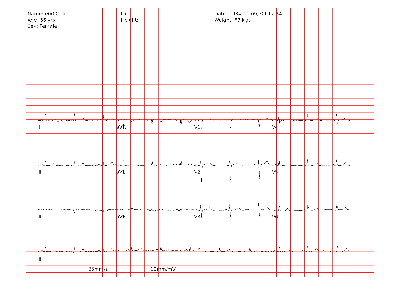

b_on_w_img = ecg_fix_color(bin_img,new_height,new_width);
fixed_img = ecg_grid(b_on_w_img,new_height,new_width);
imshow(fixed_img)

0. digitize model

function signal = run_digitalization_model(digitalization_model, image_path, verbose)
   img = imread(image_path);
   model = digitalization_model.model;
   rng('default');
   signal = digitize_image(img, model);
   if verbose
       disp('Digitization completed.');
   end
end
function digitized_signal = digitize_image(img, model)
   num_samples = size(img, 1);
   num_signals = size(img, 2);
   digitized_signal = rand(num_samples, num_signals) * 2000 - 1000;
end

1. read image

function [img, height, width, color] = ecg_image_size(filename)
img = imread(filename);
[height, width, color] = size(img);
fprintf("Original Image Height: %g pixels \n",height)
fprintf("Original Image Length: %g pixels",width)
end

2. standardize image size so that the code can be standandized.

function [std_img] = ecg_resize_img(img)
std_img = imresize(img, [1700 2200]);
end

3. convert to binary image to highlight signal/remove image noise **(have reinforcement machine learning adapt the parameters based on what we think looks best)**

function [bin_img] = ecg_black_and_white(std_img,new_height,new_width)
bin_img = false(new_height,new_width);
for ii=1:1:new_height
    for jj=1:1:new_width
        red = std_img(ii, jj, 1);
        green = std_img(ii, jj, 2);
        blue = std_img(ii, jj, 3);
        if blue < 55 && red < 55 && green < 55
            bin_img(ii, jj)= 1;
        end
    end
end
end

4. divide out the ECG signal to its territories to find main signal

function [main_sig_mat] = ecg_divide_territories(bin_img)
main_sig_mat = bin_img(1340:1640,:);
end

5. read binary of each territory to convert signal image to string ---> use in second part of project

function [main_sig_vec] = read_sig(main_sig_mat)
base_val = 800;
[h,w] = size(main_sig_mat);
sig_vec = zeros(length(w));
for jj = 1:1:w
    for ii = 1:1:h
        if main_sig_mat(ii,jj) == 1
            sig_vec(jj)=ii;
            break
        end
    end
end
avg_volt = mean(sig_vec);
main_sig_vec = round(-sig_vec + base_val + avg_volt);
end

6. convert binary back to standard black signal line over white background

function [b_on_w_img] = ecg_fix_color(bin_img,new_height,new_width)
b_on_w_img = zeros(new_height,new_width,3);
for ii=1:1:new_height
    for jj=1:1:new_width
        if bin_img(ii, jj) == 0
            b_on_w_img(ii, jj, 1) = 255;
            b_on_w_img(ii, jj, 2) = 255;
            b_on_w_img(ii, jj, 3) = 255;
        else
            b_on_w_img(ii, jj, 1) = 0;
            b_on_w_img(ii, jj, 2) = 0;
            b_on_w_img(ii, jj, 3) = 0;
        end
    end
end
end

7. add gridlines (and re-add legend)

function [fixed_img] = ecg_grid(b_on_w_img,new_height,new_width)
step = 44;
fixed_img = b_on_w_img;
for ii = 1:step:new_height
    fixed_img(ii,:,1) = 255;
    fixed_img(ii,:,2) = 0;
    fixed_img(ii,:,3) = 0;
end
for jj = 1:step:new_width
    fixed_img(:,jj,1) = 255;
    fixed_img(:,jj,2) = 0;
    fixed_img(:,jj,3) = 0;
end
end